# Exercise 1: The Radar Range Equation

This example demonstrates how to use radar system level parameters and the radar range equation to make an estimate of the returned pulse signal to noise ratio (SNR).

## MATLAB Online & Live Scripts

MATLAB Online is a slightly different experience than the typical MATLAB desktop installation.  Many of the tools will be the same, but there may be some differences in visuals and how buttons and options are displayed.

MATLAB Live Scripts are interactive documents that combine MATLAB code with formatted text, equations and images in a single environment called the Live Editor.  In addition, live scripts store and display output alongside the code that creates it.

MATLAB Live Scripts are often divided up into sections, as this one is.  To run one section at a time, use the "Run Section" button in the "Live Editor" panel highlighted below.  The traditional MATLAB "Run" button can be used to run the Live Script in its entirety.  Today, use the "Run Section" button to run one section at a time as subsequent sections are incomplete before you've added your code and running them may result in errors.

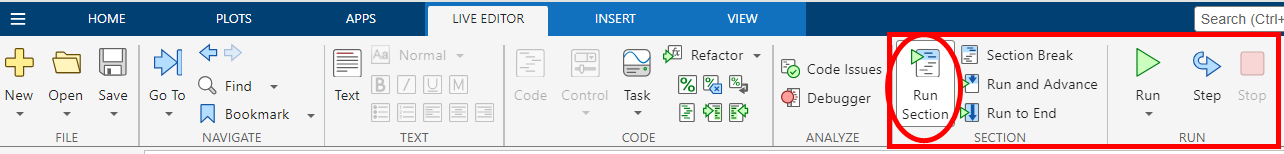

'Tab Completion' is a useful strategy to fill out function name, variable names, and input arguments.

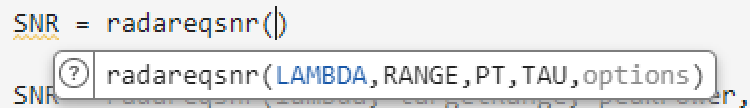

## Find Required SNR for the Desired Probability of Detection and False Alarm

The required signal to noise ratio (SNR) of a received pulse for this system can be determined from the desired probability of detection and probability of false alarm.  The higher the desired probability of detection the higher the SNR needs to be.

requiredSNR = detectability(.9,... % Probability of detection
    1e-6,...                       % Probability of false alarm
    1);                            % Number of pulses to integrate

disp(requiredSNR) % Required SNR in dB for Pd = 0.9, Pfa = 1e-6, Number of Pulses = 1

## Today's Objective

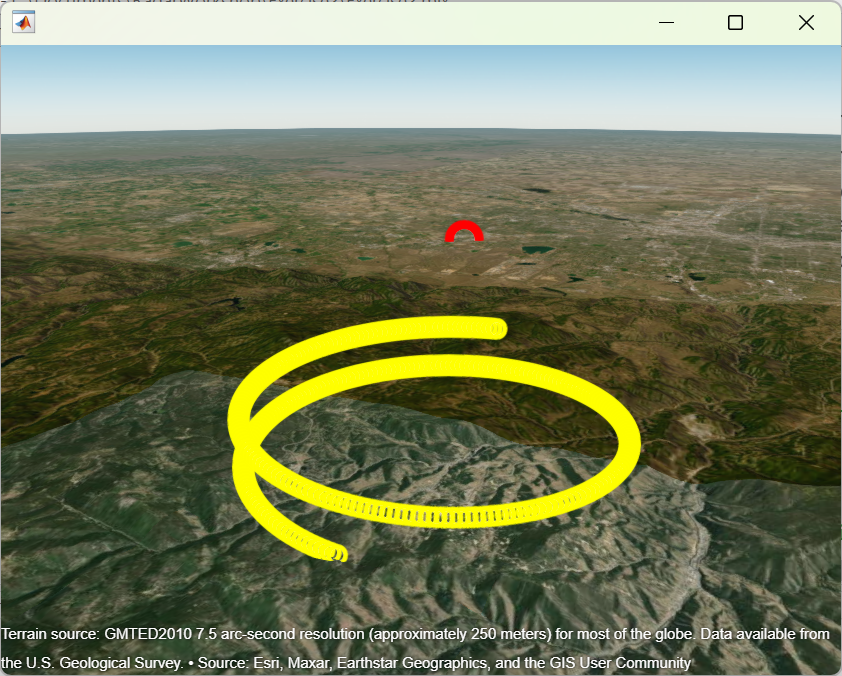

In the exercises today, you will determine whether an existing radar is able to detect a target of interest over the entirety of its flight path.  First, we will evaluate the existing radar system's performance.  Then, we will evaluate the effect of terrain on the radar's ability to detect a target.  Finally, we will perform some analysis to improve the radar if necessary.

In this case, the radar is attempting to detect an aircraft that is flying in a decending corkscrew trajectory in the Rocky Mountains in Colorado.  The aircraft flies at distances of up to 40 km away, and it is necessary to detect it for the totality of its flight.  Start off the analysis by analyzing the radar system's performance.

## Use Radar Equation to Determine Received SNR


$$SNR = \frac{P_r}{N} = \frac{P_tG^2\lambda^2\sigma}{(4\pi)^3R^4kT_sB_nL}$$


$P_t$ = Peak transmit power in watts

$G_t$ = Transmit/Receive antenna gain

$\lambda$ = Radar wavelength in meters

$\sigma$ = target's nonfluctuating radar cross secion in square meters

L = general loss facto in decibels that accounts for both system and propagation loss

$R_t$ = range from radar to target

$k$ = Boltzmann's constant

$T_s$ = System temperature ($T_s = TF_n$, $T$ = effective noise temperatrue, $F_n$ = Noise Factor)

$B_n$ = bandwidth of the system (equal to the reciprocal of pulse width)

frequency = 6e9;                  % Hz
lambda = freq2wavelen(frequency); % signal wavelength in meters
MaxRangeRq = 40e3;                % Maximum range requirement (m)
range = MaxRangeRq;               % target range is ~40 kilometers (units are meters)
pt = 1e3;                         % peak radar power in Watts
tau = 1e-6;                       % radar pulse width in seconds
rcs = 10;                         % target radar cross section is ~10 m^2.  This is a name/value pair argument (use RCS=rcs syntax)
ts = 290;                         % system noise temperature in Kelvin.  This is a name/value pair argument (use Ts=ts syntax)

% For a monostatic radar system, the same hardware is used for transmit and
% receive, so the tx and rx antenna gain will be identical
hpbw = [2; 5];                    % [az;el] degrees (clarify single sided vs. double sided)                                                  
gain = beamwidth2gain(hpbw, ...   % gain in dBi.  This is a name/value pair argument (use Gain=gain syntax)
    'CosineRectangular'); 

%---------------------------------------------------------------------------------------------------
% ADD CODE HERE
% Hint: use the 'radareqsnr' function to calculate the signal to noise
% ratio of the received signal from the target of interest.  Type 'doc
% radareqsnr' into the command line interface for more information.  Supply
% the wavelength, target range, power, pulse width, RCS, system
% temperature and gain as inputs.  Call the output SNR.

%---------------------------------------------------------------------------------------------------

disp(SNR); % Received SNR for a single pulse reflected from the target of interest at the range of interest in dB

## View Returned SNR as a Function of Range

Now calculate the signal to noise ratio as a function of range.  For this system, plot the SNR as a function of range from 20 to 60 km.

ranges = linspace(20e3, 60e3, 100).'; % Ranges from 20 to 60 km in meters

%---------------------------------------------------------------------------------------------------
% ADD CODE HERE
% Hint: use the 'radareqsnr' function to calculate the signal to noise
% ratio of the received signal from the target of interest.  Type 'doc
% radareqsnr' into the command line interface for more information.  The
% range can be specified as a vector to see the signal to noise ratio as a
% function of range.  The arguments for this function call otherwise are
% the same as above.  Call the output SNR.

%---------------------------------------------------------------------------------------------------

plot(ranges * 1e-3, SNR)
yline(requiredSNR, '--r')
xline(MaxRangeRq/1000, '--r')
title("SNR vs. Range")
ylabel('SNR (dB)')
xlabel('Target Range (km)')
xlim([20, 60])
grid on

## View SNR plot in a Radar Metric Plot as a Function of Range

Now we plot the SNR as a function of range from 20 to 60 km using a radar metric plot, which is a slightly clearer way to show this information.

metricName = 'Available SNR';
metricUnit = 'dB';
requirementName = 'Required SNR';
showStoplight = true;

%---------------------------------------------------------------------------------------------------
% ADD CODE HERE
% Hint: use the 'radarmetricplot' function to plot the signal to noise
% ratio of the received signal from the target of interest.  Type 'doc
% radarmetricplot' into the command line interface for more information.  The
% range can be specified as a vector as above.  All the lines we add after the fact 
% are part of the main function call.

% Supply ranges, SNR, and requiredSNR as value only arguments.
% Supplly MaxRangeRq, metricName, metricUnit, requirementName,
% and showStoplight as name-value pairs (Name=Value syntax).

%---------------------------------------------------------------------------------------------------

% plot controls work here as with the traditional plot command
xlim([20, 60]*1000)
ylim([0 40])

#### Exercise Question: Is the target detectable with the required probability over all required ranges?

## Conclusion

Based on the analysis from this exercise, it is apparent that the SNR from a pulse returned by the target of interest at its maximum range (40 km) will not be sufficient to support the required probability of detection of 0.9.  The next exercise will examine the effect of the scenario geometry including flight trajectories and 